# Class 14/10

## 5. Traitement d'images

### 5.1 Definitions

Une image réelle est un signal continu bidimensionnel. Une image numérique est définie à partir d'un signal fini bidimensionnel échantillonné à valeurs quantifiées dans un certain espace de couleurs. Elle est constituée de  pixels (cases).

- fini: Un image a un taille NxM

- échantillonné: L'image est découpé en un grille régulière. 1 case = 1 pixel = 1 valeur

- valeurs quantifiées: Les valeurs des pixels appartiennet à un intervalle borné.

- espace de couleurs: par exemple RGB

### 5.2 Image = matrice

Une image nùmerique est considérée comme une matrice de taille NxM

#### 5.2.1 Image Binaire (= logique)

Les pixels ne peuvent pendre que la valeur 0 ou 1 (noir ou blanc)

#### 5.2.2 Image en niveau de gris

Dégradé entre le noir et le blanc les pixels prennent des valeurs entières entre 0 et ((2^n) - 1) pour un image n bits

#### 5.2.3 Image couleur

C'est la composition / superposition de 3 images en niveaux de gris

### 5.3 Lire et afficher l'image

Pour accéder (= lire) une image

clc; clear; close all;
I = imread("images\crayons_couleurs.png");
figure()
imshow(I);

**Exercise:** 

- *Sur un même figure, afficherl'image initiale et les 3 niveaux de gris la composant*

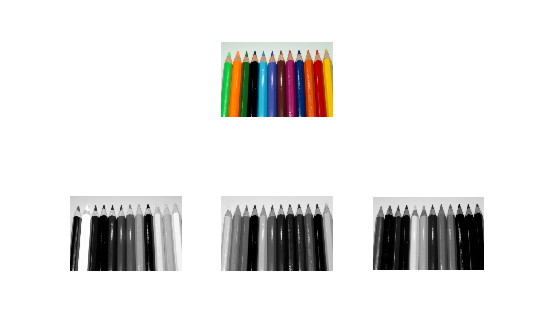

figure()
subplot(2, 3, 2);
imshow(I);
subplot(2,3,4);
imshow(I(:,:,1));
subplot(2,3,5);
imshow(I(:,:,2));
subplot(2,3,6);
imshow(I(:,:,3));

- *Enlever (= annuler) la composante rouge et visualiser le résultat idem pour vert puis pour bleu*

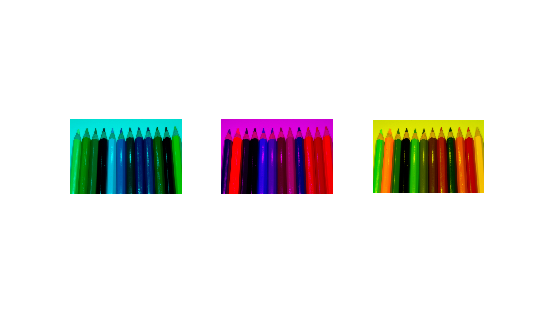

I_sans_rouge = I;
I_sans_rouge(:,:,1) = 0;
I_sans_vert = I;
I_sans_vert(:,:,2) = 0;
I_sans_bleu = I;
I_sans_bleu(:,:,3) = 0;

figure()
subplot(1,3,1);
imshow(I_sans_rouge);
subplot(1,3,2);
imshow(I_sans_vert);
subplot(1,3,3);
imshow(I_sans_bleu);

- *Ne garder que la composante rouge (= annuler vert et bleu) et visualiser le résultat idem pour vert puis bleu*

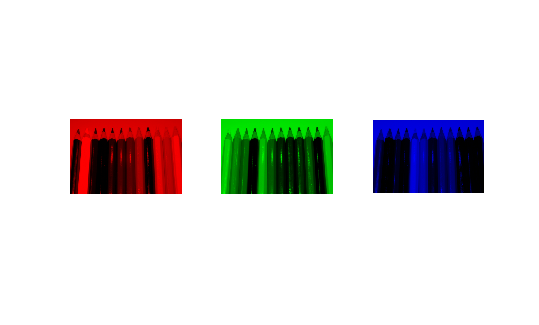

I_rouge = I;
I_rouge(:,:,2) = 0;
I_rouge(:,:,3) = 0;

I_vert = I;
I_vert(:,:,1) = 0; 
I_vert(:,:,3) = 0;

I_bleu = I;
I_bleu(:,:,1) = 0; 
I_bleu(:,:,2) = 0;

figure()
subplot(1,3,1);
imshow(I_rouge);
subplot(1,3,2);
imshow(I_vert);
subplot(1,3,3);
imshow(I_bleu);

### 5.4 Modifier type image

- Pour passer d'un image couleur à un image en niveaux de gris **rgb2gray(I);**

- Pour passer d'un image niveaux de gris à un image bineire: **im2bw(I);**

- Pour passer d'une image couleur RGB à un image couleur HSV (Hue Saturation and Value): **rgb2hsv(I);**

*Exercise: Afficher côte à côte image initialie, ilage niveaux de gris, image binaire et image HSV*

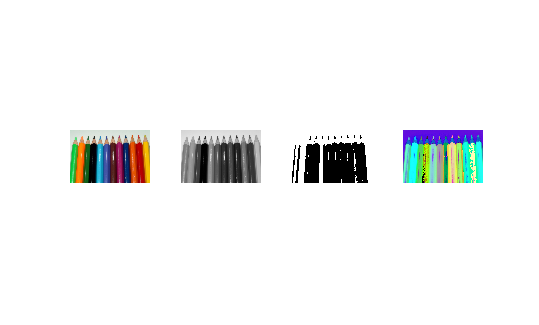

figure()
subplot(1,4,1);
imshow(I);
subplot(1,4,2);
imshow(rgb2gray(I));
subplot(1,4,3);
imshow(im2bw(rgb2gray(I)));
subplot(1,4,4);
imshow(rgb2hsv(I));

### 5.5 Redimensionner 1 image

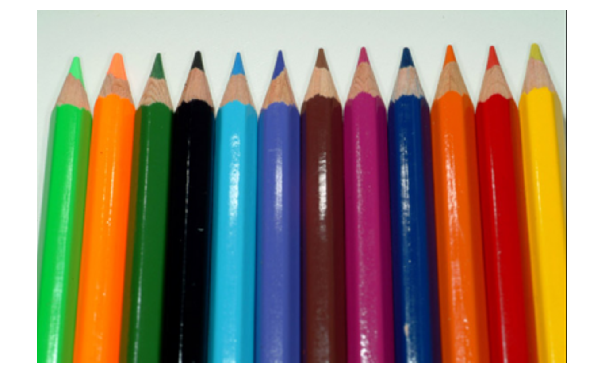

figure()
J = imresize(I, [798 1200]);
imshow(J)

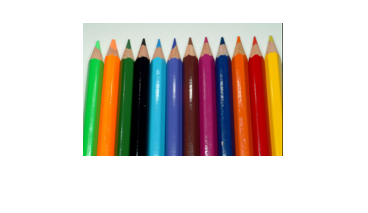

J = imresize(I, [133 200]);
imshow(J)

### 5.6 Couper un image

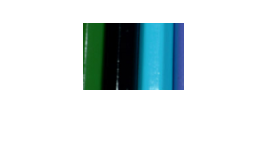

%           xmin ymin width height
J = imcrop(bwImage , [75 200 100 100]);
imshow(J)

### 5.7 Histogramme

L'histogramme d'un image represente la repqrtition des valeurs de pixels dans l'image. On dit le nombre des pixels en fonction de leur valeur

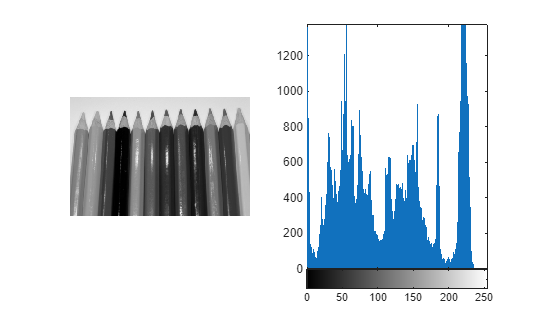

figure();
subplot(1,2,1);
imshow(rgb2gray(I));
subplot(1,2,2);
imhist(rgb2gray(I));

Lorsque l'hsitogramme d'une image n'est pas satisfaisant, on peut modifier l'image

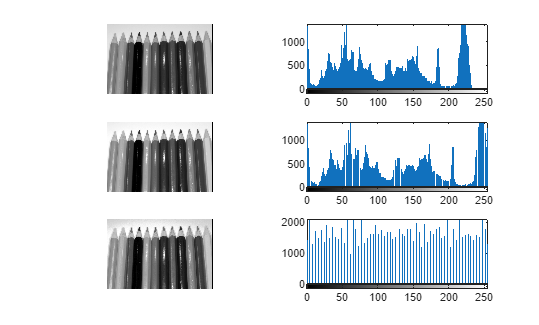

I_gray = rgb2gray(I);
figure()
subplot(3,2,1);
imshow(I_gray);
subplot(3,2,2);
imhist(I_gray);
subplot(3,2,3);
imshow(imadjust(I_gray));
subplot(3,2,4);
imhist(imadjust(I_gray));
subplot(3,2,5);
imshow(histeq(I_gray));
subplot(3,2,6);
imhist(histeq(I_gray));